与图床边界的距离为0.5个单元长度/宽度

dL = 0.5*abs((Coordinate(Ielement(1,2),1)-Coordinate(Ielement(1,1),1)));
dW = 0.5*abs((Coordinate(Ielement(1,4),2)-Coordinate(Ielement(1,1),2)));

% iNode = 1:20;
iNode= n.left ;% 绘制的节点编号

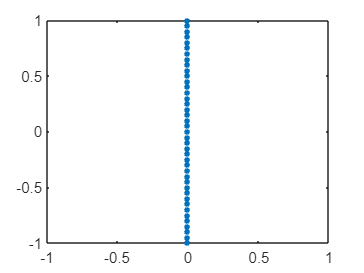

figure
plot(Coordinate(iNode,1),Coordinate(iNode,2),'.','MarkerSize',10)

error("按键运行动画")

按键运行动画

动画

 
t = 1e-2; % 动画帧时间
figure()
plot(nan,nan)
hold on
xlim([min(Coordinate(iNode(:),1)-dL),max(Coordinate(iNode(:),1))+dL]);
ylim([min(Coordinate(iNode(:),2)-dW),max(Coordinate(iNode(:),2))+dW]);

for ii = 1:length(iNode)
	i = iNode(ii);
	plot(Coordinate(i,1),Coordinate(i,2),'.','MarkerSize',10)
% 	xlim([min(Coordinate(iNode,1)-dL),max(Coordinate(iNode,1))+dL])
% 	ylim([min(Coordinate(iNode,2)-dW),max(Coordinate(iNode,2))+dW])
	text(Coordinate(i,1),Coordinate(i,2),num2str(i),'FontSize',6,'VerticalAlignment','top','HorizontalAlignment','left')
	pause(t)
	hold on
end
% axis padded
hold off